# FF_VFI_AZ_MZOOM_VEC Savings Vectorized Exact (VALUE) Examples

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function:[** ff_vfi_az_mzoom_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_mzoom_vec.m) from the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **This function solves the dynamic programming problem for a (a,z) model. The state-space is on a grid, but choice grids are in terms of percentage of resources to save and solved exactly. 

This is a **vectorized** code for **continuous** choices, solved with the [**mzoom**](https://fanwangecon.github.io/MEconTools/MEconTools/doc/optim/htmlpdfm/fx_optim_mzoom_savezrone.html) algorithm. In contrast to the [**bisection**](https://fanwangecon.github.io/MEconTools/MEconTools/doc/optim/htmlpdfm/fx_optim_bisec_savezrone.html) based solution, this is slower, but this does not rely on first order conditions.

**Links to Other Code:**

Core Savings/Borrowing Dynamic Programming Solution Functions that are functions in the [**MEconTools Package**](https://fanwangecon.github.io/MEconTools/)**. **:

- Common Choice and States Grid ***Loop***: [**ff_vfi_az_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_loop.m)

- Common Choice and States Grid ***Vectorized***:  [**ff_vfi_az_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_vec.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, rely on FOC, ***Loop***:[** ff_vfi_az_bisec_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_loop.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, rely on FOC ***Vectorized***: [**ff_vfi_az_bisec_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_bisec_vec.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, VALUE comparison, ***Loop***:[** ff_vfi_az_mzoom_loop**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_mzoom_loop.m)

- States Grid + Continuous Exact Savings as Share of Cash-on-Hand, VALUE comparison, ***Vectorized***: [**ff_vfi_az_mzoom_vec**](https://github.com/FanWangEcon/MEconTools/blob/master/MEconTools/vfi/ff_vfi_az_mzoom_vec.m)

## Test FF_VFI_AZ_MZOOM_VEC Defaults

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('fl_crra') = 1.5;
mp_params('fl_beta') = 0.94;
% call function
ff_vfi_az_mzoom_vec(mp_params);

Elapsed time is 6.126702 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
          i    idx    ndim    numel    rowN    colN     sum       mean      std      coefvari    min     max  
          _    ___    ____    _____    ____    ____    ______    ______    ______    ________    ___    ______

    ap    1     1      2       700     100      7      9861.5    14.088    14.386     1.0212      0     50.115

xxx TABLE:ap xxxxxxxxxxxxxxxxxx
    

## Test FF_VFI_AZ_MZOOM_VEC Speed Tests

Call the function with defaults. By default, shows the asset policy function summary. Model parameters can be changed by the mp_params.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('ls_ffcmd') = {};
% A grid 50, shock grid 5:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 1.996365 seconds.


% A grid 750, shock grid 15:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 15;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 337.171768 seconds.


% A grid 600, shock grid 45:
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 600;
mp_params('it_z_n') = 45;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 1758.273287 seconds.


## Test FF_VFI_AZ_MZOOM_VEC Control Outputs

Run the function first without any outputs, but only the timer.

mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 50;
mp_params('it_z_n') = 5;
mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_timer') = true;
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {};
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 1.091918 seconds.


Run the function and show policy function for savings choice. For ls_ffcmd, ls_ffsna, ls_ffgrh, can include these: 'v', 'ap', 'c', 'y', 'coh', 'savefraccoh'. These are value, aprime savings choice, consumption, income, cash on hand, and savings fraction as cash-on-hand.

Elapsed time is 1.090424 seconds.
xxx  ff_vfi_az_vec, outcome=savefraccoh  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group       a        mean_z_0_4858    mean_z_0_67798    mean_z_0_9462    mean_z_1_3205    mean_z_1_8429
    _____    ________    _____________    ______________    _____________    _____________    _____________

      1             0             0                 0         0.067148           0.2084          0.35952   
      2      0.002975             0                 0         0.069345          0.20826          0.36029   
      3      0.016829             0                 0         0.070749           0.2136          0.36206   
      4      0.046375             0         0.0059631          0.08732          0.22641          0.36263   
      5   

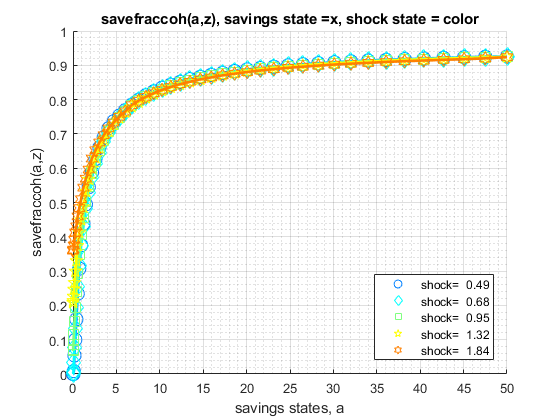

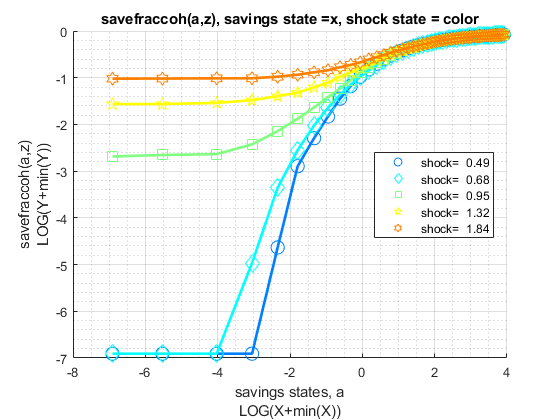

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
% ls_ffcmd: summary print which outcomes
mp_support('ls_ffcmd') = {};
% ls_ffsna: detail print which outcomes
mp_support('ls_ffsna') = {'savefraccoh'};
% ls_ffgrh: graphical print which outcomes
mp_support('ls_ffgrh') = {'savefraccoh'};
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Run the function and show summaries for savings and fraction of coh saved:

Elapsed time is 5.173849 seconds.
xxx  ff_vfi_az_vec, outcome=savefraccoh  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group        a         mean_z_0_36853    mean_z_0_46648    mean_z_0_59047    mean_z_0_74742    mean_z_0_94608    mean_z_1_1975    mean_z_1_5159    mean_z_1_9188    mean_z_2_4288
    _____    __________    ______________    ______________    ______________    ______________    ______________    _____________    _____________    _____________    _____________

       1              0               0                0                 0                  0         0.065547          0.16519          0.27438          0.37

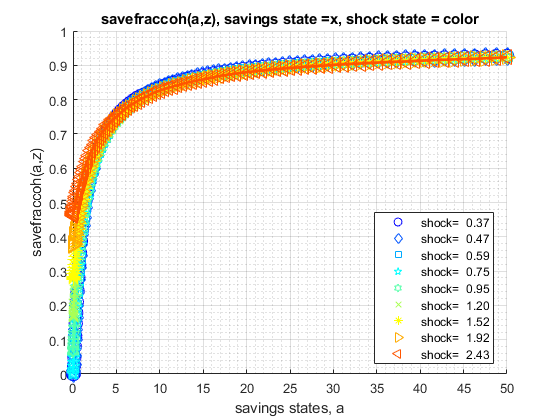

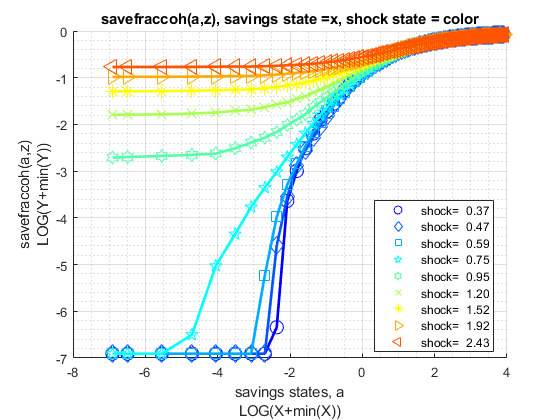

%mp_params
mp_params = containers.Map('KeyType','char', 'ValueType','any');
% mp_params('fl_crra') = 1.5;
% mp_params('fl_beta') = 0.94;
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 9;
mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
% ls_ffcmd: summary print which outcomes
mp_support('ls_ffcmd') = {};
% ls_ffsna: detail print which outcomes
mp_support('ls_ffsna') = {'savefraccoh'};
% ls_ffgrh: graphical print which outcomes
mp_support('ls_ffgrh') = {'savefraccoh'};
% call function
ff_vfi_az_mzoom_vec(mp_params, mp_support);

## Test FF_VFI_AZ_MZOOM_VEC Change Interest Rate and Discount

Show only save fraction of cash on hand:

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 750;
mp_params('it_z_n') = 9;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with several different interest rates and discount factor:

% Lower Savings Incentives
mp_params('fl_beta') = 0.80;
mp_params('fl_r') = 0.01;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 37.005214 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    ______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      3468.2    0.5138    0.27192    0.52924      0     0.80103

xx

% Higher Savings Incentives
mp_params('fl_beta') = 0.95;
mp_params('fl_r') = 0.04;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 159.606266 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    ______    _______    ________    ___    _______

    savefraccoh    1     1      2      6750     750      9      4667.7    0.6915    0.26685     0.3859      0     0.92668

x

## Test FF_VFI_AZ_MZOOM_VEC Changing Risk Aversion

Here, again, show fraction of coh saved in summary tabular form, but also show it graphically.

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {'savefraccoh'};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 100;
mp_params('it_z_n') = 7;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Solve the model with different risk aversion levels, higher preferences for risk:

Elapsed time is 3.409484 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2       700     100      7      452.03    0.64575    0.28029    0.43406      0     0.90354



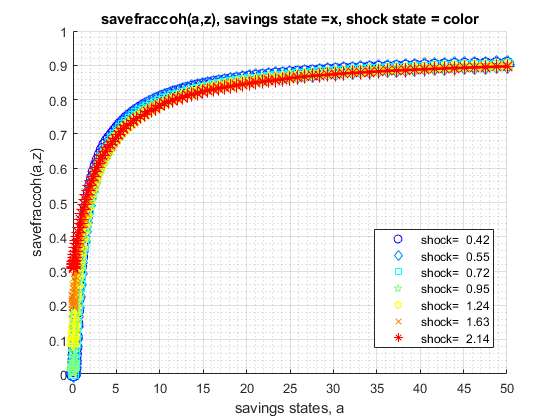

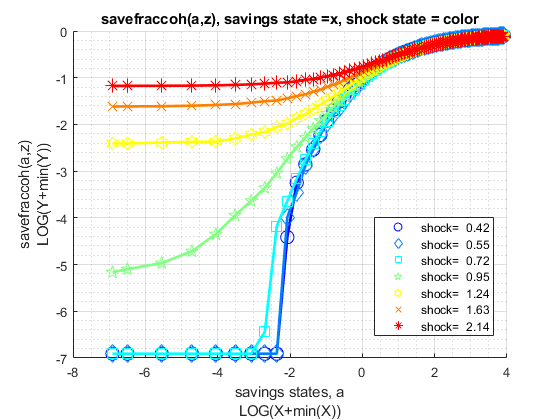

% Lower Risk Aversion
mp_params('fl_crra') = 0.5;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

When risk aversion increases, at every state-space point, the household wants to save more.

Elapsed time is 4.012888 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum     mean       std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    _____    _____    _______    ________    ___    _______

    savefraccoh    1     1      2       700     100      7      502.6    0.718    0.25437    0.35427      0     0.93587

xxx TABLE

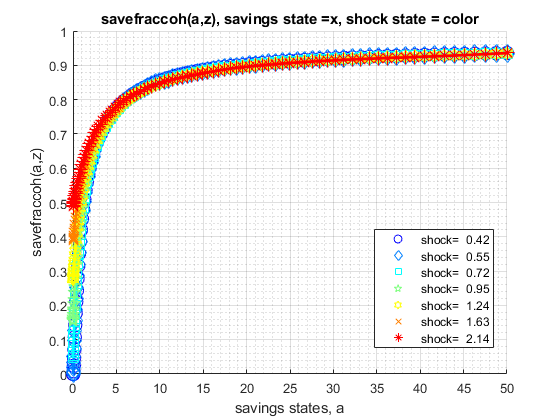

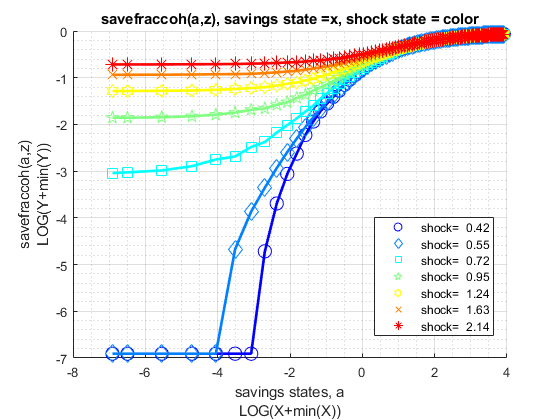

% Higher Risk Aversion
mp_params('fl_crra') = 5;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

## Test FF_VFI_AZ_MZOOM_VEC with Higher Uncertainty

Increase the standard deviation of the Shock. 

mp_support = containers.Map('KeyType','char', 'ValueType','any');
mp_support('bl_print_params') = false;
mp_support('bl_print_iterinfo') = false;
mp_support('ls_ffcmd') = {'savefraccoh'};
mp_support('ls_ffsna') = {};
mp_support('ls_ffgrh') = {};
mp_params = containers.Map('KeyType','char', 'ValueType','any');
mp_params('it_a_n') = 150;
mp_params('it_z_n') = 15;
mp_params('fl_a_max') = 50;
mp_params('st_grid_type') = 'grid_powerspace';

Lower standard deviation of shock:

% Lower Risk Aversion
mp_params('fl_shk_std') = 0.10;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 16.599473 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      2250     150      15     1507.2    0.66985    0.28667    0.42796      0     0.92565


Higher shock standard deviation: low shock high asset save more, high shock more asset save less, high shock low asset save more:

% Higher Risk Aversion
mp_params('fl_shk_std') = 0.40;
ff_vfi_az_mzoom_vec(mp_params, mp_support);

Elapsed time is 16.323916 seconds.
----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_ffcmd ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                   i    idx    ndim    numel    rowN    colN     sum       mean        std      coefvari    min      max  
                   _    ___    ____    _____    ____    ____    ______    _______    _______    ________    ___    _______

    savefraccoh    1     1      2      2250     150      15     1685.2    0.74898    0.22908    0.30585      0     0.93669
